# **两次优化**

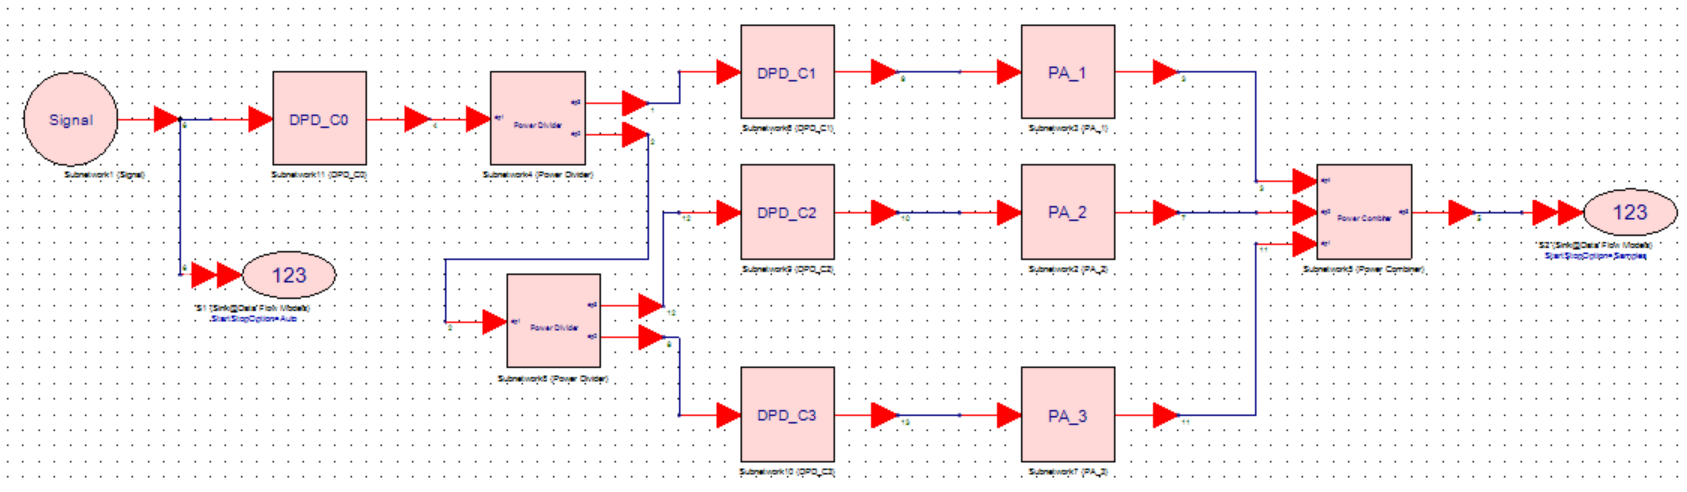

% 运行前请先将子文件夹添加到路径
clc;

## -----------------------------Model C Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4);
PA2_output = Data_matrix(:,5) + 1i * Data_matrix(:,6);
PA3_output = Data_matrix(:,7) + 1i * Data_matrix(:,8);
PA1_input = 0.5*Sys_input;
PA2_input = 0.25*Sys_input;
PA3_input = 0.25*Sys_input;
% 参数需要保持一致
M = 4;
PA1_flag = 0;
PA2_flag = 0;
PA3_flag = 0;
Whole_flag = 1;
times = 5;
load('nmse_min.mat', 'nmse_min');

---------- 1 ---------

PA3模型的拟合精度NMSE为 -55.178727 dB


PA2模型的拟合精度NMSE为 -57.165264 dB


PA1模型的拟合精度NMSE为 -50.534569 dB


【第一次迭代后，整体的NMSE为 -47.046847 dB】


第一次迭代后，PA1的NMSE为 -41.809679 dB


第一次迭代后，PA2的NMSE为 -50.717755 dB


第一次迭代后，PA3的NMSE为 -51.824303 dB


【本次训练迭代了 1000.000000 轮】


整体的拟合精度NMSE为 -57.189342 dB


第二次迭代后，PA1的NMSE为 -35.502100 dB


第二次迭代后，PA2的NMSE为 -49.541455 dB


第二次迭代后，PA3的NMSE为 -51.100217 dB


【使用Model C，系统的NMSE仿真结果为 -42.749893 dB】


---------- 2 ---------

PA3模型的拟合精度NMSE为 -55.178727 dB


PA2模型的拟合精度NMSE为 -57.165264 dB


PA1模型的拟合精度NMSE为 -50.534569 dB


【第一次迭代后，整体的NMSE为 -47.046847 dB】


第一次迭代后，PA1的NMSE为 -41.809679 dB


第一次迭代后，PA2的NMSE为 -50.717755 dB


第一次迭代后，PA3的NMSE为 -51.824303 dB


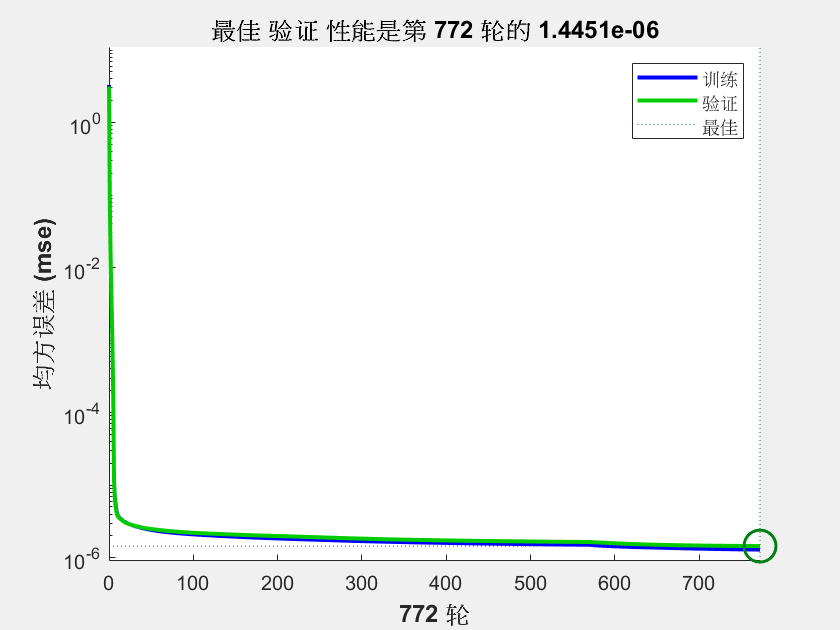

% 优化迭代
for ii=1:times
    fprintf('---------- %d ---------',ii);
    %% 训练PA3
    path_temp = 'Method_C\PA3\FNN_opt.mat';
    if (PA3_flag)
        % 模型训练
        [model,tr] = Train_sim(M,PA3_input,PA3_output,[32,24],0);
        fprintf('本次训练迭代了 %f 轮\n', tr.num_epochs);
        save(path_temp, 'model');
    end
    % 模型精度
    [model_input,model_output] = pre_train(M,PA3_input,PA3_output,dim);
    data = load(path_temp);
    DPD_output_m = sim(data.model,model_input);
    DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
    nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
    fprintf('PA3模型的拟合精度NMSE为 %f dB\n', nmse);

    %% 训练PA2
    path_temp = 'Method_C\PA2\FNN_opt.mat';
    if (PA2_flag)
        % 模型训练
        [model,tr] = Train_sim(M,PA2_input,PA2_output,[32,24,8],0);
        fprintf('本次训练迭代了 %f 轮\n', tr.num_epochs);
        save(path_temp, 'model');
    end
    % 模型精度
    [model_input,model_output] = pre_train(M,PA2_input,PA2_output,dim);
    data = load(path_temp);
    DPD_output_m = sim(data.model,model_input);
    DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
    nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
    fprintf('PA2模型的拟合精度NMSE为 %f dB\n', nmse);

    %% 训练PA1
    path_temp = 'Method_C\PA1\FNN_opt.mat';
    if (PA1_flag)
        % 模型训练
        [model,tr] = Train_sim(M,PA1_input,PA1_output,[32,24,8],0);
        fprintf('本次训练迭代了 %f 轮\n', tr.num_epochs);
        save(path_temp, 'model');
    end
    % 模型精度
    [model_input,model_output] = pre_train(M,PA1_input,PA1_output,dim);
    data = load(path_temp);
    DPD_output_m = sim(data.model,model_input);
    DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
    nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
    fprintf('PA1模型的拟合精度NMSE为 %f dB\n', nmse);

    %% 第一次迭代
    [A1_input,A23] = Power_Divider(Sys_input);
    [A2_input,A3_input] = Power_Divider(A23);
    A1_input_DPD1 = DPD_sim(A1_input,M,'Method_C\PA1\FNN_opt.mat');
    A1_output = PA_1(A1_input_DPD1);
    A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN_opt.mat');
    A2_output = PA_2(A2_input_DPD);
    A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN_opt.mat');
    A3_output = PA_3(A3_input_DPD);
    Sys_output_middle = Power_Combiner(A1_output,A2_output,A3_output);
    % 中间评估
    nmse_middle = NMSE_dB(Sys_input,Sys_output_middle);
    nmse_1 = NMSE_dB(A1_input,A1_output);
    nmse_2 = NMSE_dB(A2_input,A2_output);
    nmse_3 = NMSE_dB(A3_input,A3_output);
    fprintf('【第一次迭代后，整体的NMSE为 %f dB】\n', nmse_middle);
    fprintf('第一次迭代后，PA3的NMSE为 %f dB\n', nmse_3);
    fprintf('第一次迭代后，PA2的NMSE为 %f dB\n', nmse_2);
    fprintf('第一次迭代后，PA1的NMSE为 %f dB\n', nmse_1);

    %% 整体训练
    path_temp = 'Method_C\Whole\FNN_temp.mat';
    if (Whole_flag)
        % 模型训练
        [model,tr] = Train_sim(M,Sys_input,Sys_output_middle,[32,24],0);
        fprintf('【本次训练迭代了 %f 轮】\n', tr.num_epochs);
        save(path_temp, 'model');
    end
    % 模型精度
    [model_input,model_output] = pre_train(M,Sys_input,Sys_output_middle,dim);
    data = load(path_temp);
    DPD_output_m = sim(data.model,model_input);
    DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
    nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
    fprintf('整体的拟合精度NMSE为 %f dB\n', nmse);

    %% 第二次迭代
    Sys_input_DPD=DPD_sim(Sys_input,M,'Method_C\Whole\FNN_temp.mat'); % DPD
    [A1_input,A23] = Power_Divider(Sys_input_DPD);
    [A2_input,A3_input] = Power_Divider(A23);
    A1_input_DPD1 = DPD_sim(A1_input,M,'Method_C\PA1\FNN_temp.mat'); % DPD
    A1_output = PA_1(A1_input_DPD1);
    A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN_temp.mat'); % DPD
    A2_output = PA_2(A2_input_DPD);
    A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN_temp.mat'); % DPD
    A3_output = PA_3(A3_input_DPD);
    Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
    
    %% 最终性能评估
    nmse_now = NMSE_dB(Sys_input,Sys_output);
    nmse_1 = NMSE_dB(A1_input,A1_output);
    nmse_2 = NMSE_dB(A2_input,A2_output);
    nmse_3 = NMSE_dB(A3_input,A3_output);
    fprintf('第二次迭代后，PA3的NMSE为 %f dB\n', nmse_3);
    fprintf('第二次迭代后，PA2的NMSE为 %f dB\n', nmse_2);
    fprintf('第二次迭代后，PA1的NMSE为 %f dB\n', nmse_1);
    % Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD');
    fprintf('【使用Model C，系统的NMSE仿真结果为 %f dB】\n', nmse_now);
    
    %% 保留最佳结果
    if(nmse_now<nmse_min)
        nmse_min=nmse_now;
        save('nmse_min.mat', 'nmse_min');
        %
        % data = load('Method_C\PA3\FNN_temp.mat');
        % model = data.model;
        % save('Method_C\PA3\FNN_opt.mat', 'model');
        %
        % data = load('Method_C\PA2\FNN_temp.mat');
        % model = data.model;
        % save('Method_C\PA2\FNN_opt.mat', 'model');
        %
        % data = load('Method_C\PA1\FNN_temp.mat');
        % model = data.model;
        % save('Method_C\PA1\FNN_opt.mat', 'model');
        %
        data = load('Method_C\Whole\FNN_temp.mat');
        model = data.model;
        save('Method_C\Whole\FNN_opt.mat', 'model');
    end
end

## -----------------------------Model C Valid----------------------------

## 读取数据

% clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
% 参数需要保持一致
M = 4;

## Model Test

% 系统仿真
Sys_input_DPD=DPD_sim(Sys_input,M,'Method_C\Whole\FNN_opt.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_sim(A1_input,M,'Method_C\PA1\FNN_opt.mat'); % DPD
% A1_input_DPD2 = DPD_sim(A1_input_DPD1,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN_opt.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN_opt.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+2M）个值
Sys_input = Sys_input(5+M*2:end);
Sys_output = Sys_output(5+M*2:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD_predict');
nmse_now= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_now);